5.1 - Image Manipulation

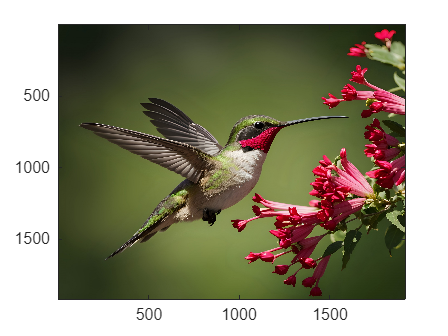

%5.1.1 

% In this step, we will read and image, transform it to double form of
% greyscale, as well as the RGB intensity values

    % Reading rectangle image
        X = imread('square.jpg');
        imagesc(X)

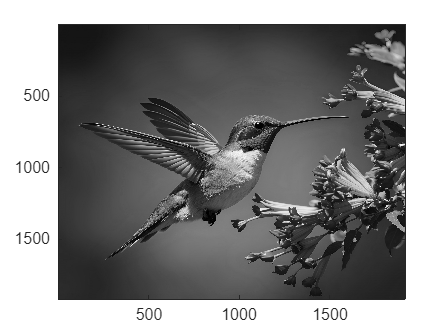

    
    % Convert X matrix to double datatype
        X_double = double(X);
        % Setting Variable that will be used in question below
            R = X_double(:,:,1);
            G = X_double(:,:,2);
            B = X_double(:,:,3);
        
    % Convert to double (data type) greyscale image and read greyscale image
    
        X_gray= X_double(:,:,1)/3.0 + X_double(:,:,2)/3.0 + X_double(:,:,3)/3.0;
            % Side note, this is taking the average of each intensity and
            % linearly combining it into 1 matrix
        imagesc(uint8(X_gray))
        colormap('gray')

        
        X_gray % Intensity values of greyscale matrix

X_gray =    22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   21.0000   21.0000   22.0000   22.0000   22.0000   21.0000   20.0000   22.0000   21.0000   21.0000   20.0000   20.0000   20.0000   20.0000   21.0000   20.0000   21.0000   21.0000   21.0000   20.0000   20.0000   21.0000   21.0000   21.0000   21.0000
   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   22.0000   21.0000   21.0000   22.0000   21.0000   21.0000   21.0000   20.0000   20.0000   21.0000   21.0000   20.0000   21.0000   21.0000   21.0000   20.0000   20.0000   20.0000   21.0000   20.0000

    
        % Intensity Values of RGB
            % Red
        X_R_Intensity = R

X_R_Intensity =     21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    20    20    21    21    21    20    19    21    20    20    19    19    19    19    20    19    20    20    20    19    19    20    20    20    20
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    20    20    21    20    20    20    19    19    20    20    19    20    20    20    19    19    19    20    19    19
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    20    20    20    20    20    20    20    20    20    20    20    19    19    19    20    20    20    19    20    20
    21    21    21    21    21    21    21    21    21    21    21    21    21   

            % Green
        X_G_Intensity = G

X_G_Intensity =     29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    28    28    29    29    29    28    27    29    28    28    27    27    27    27    28    27    28    28    28    27    27    28    28    28    28
    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    28    28    29    28    28    28    27    27    28    28    27    28    28    28    27    27    27    28    27    27
    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    28    28    28    28    28    28    28    28    28    28    28    27    27    27    28    28    28    27    28    28
    29    29    29    29    29    29    29    29    29    29    29    29    29   

            % Blue
        X_B_Intensity = B

X_B_Intensity =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    15    15    16    16    16    15    14    16    15    15    14    14    14    14    15    14    15    15    15    14    14    15    15    15    15
    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    15    15    16    15    15    15    14    14    15    15    14    15    15    15    14    14    14    15    14    14
    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    15    15    15    15    15    15    15    15    15    15    15    14    14    14    15    15    15    14    15    15
    16    16    16    16    16    16    16    16    16    16    16    16    16   

        % Creating new Image
            imwrite(uint8(X_gray),'5.1.1_square.jpg')

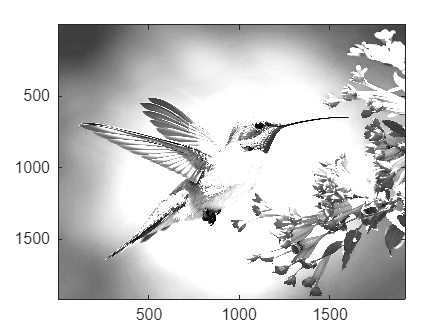

% 5.1.2

% In this step we need to change the exposure of the image to look more
% whited out. My idea is to multiply the intesity of the RBG matrixes by a
% scalar multiple (somthing > 1) to achieve this.
    exposure = 3;
    % Scaling R by 3
        X_R_Whitedout = exposure .* R;
    % Scaling R by 3
        X_G_Whitedout = exposure .* G;
    % Scaling R by 3
        X_B_Whitedout = exposure .* B;
    % Combining these back into a greyscale image
        X_gray_Whitedout = X_R_Whitedout /3.0 + X_G_Whitedout /3.0 + X_B_Whitedout /3.0;
        imagesc(uint8(X_gray_Whitedout))
        colormap('gray')

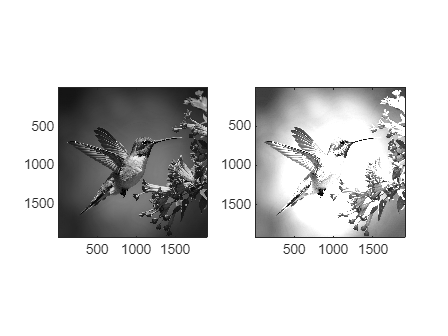

    % Creating new image
        imwrite(uint8(X_gray_Whitedout),'5.1.2_square.jpg')
    % Create a subplot of both greyscale images next to each other.
        subplot(1,2,1) % Normal Grayscale
        imagesc(uint8(X_gray))
        colormap('gray')
        axis square
        
        subplot(1,2,2) % Grayscale with greater contrast
        imagesc(uint8(X_gray_Whitedout))
        colormap('gray')
        axis square

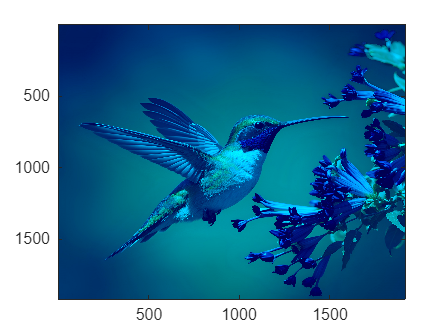

%5.1.3

% In this section, we are eliminating the red from the image and adding 80
% to the blue value intensity.
    
    % Creating Elim red
        X_elim_red = double(X);
    % Setting R intensity = 0
        X_elim_red(:,:,1) = 0;
    % Setting G intensity = G
        X_elim_red(:,:,2) = X_elim_red(:,:,2);
    % Setting B intensity = 80 + B
        X_elim_red(:,:,3) = X_elim_red(:,:,3) + 80;
    % Assembling image 
        figure;
        imagesc(uint8(X_elim_red))

    % Creating new image with changes
        imwrite(uint8(X_elim_red),'5.1.3_square.jpg')

%5.1.5






